# This code shows how to use a naive Bayes classification model.

Load Fisher's iris data set.

load fisheriris
X = meas(:,1:2);
Y = species;
labels = unique(Y);

`X` is a numeric matrix that contains two petal measurements for 150 irises. `Y` is a cell array of character vectors that contains the corresponding iris species.

Visualize the data using a scatter plot. Group the variables by iris species.

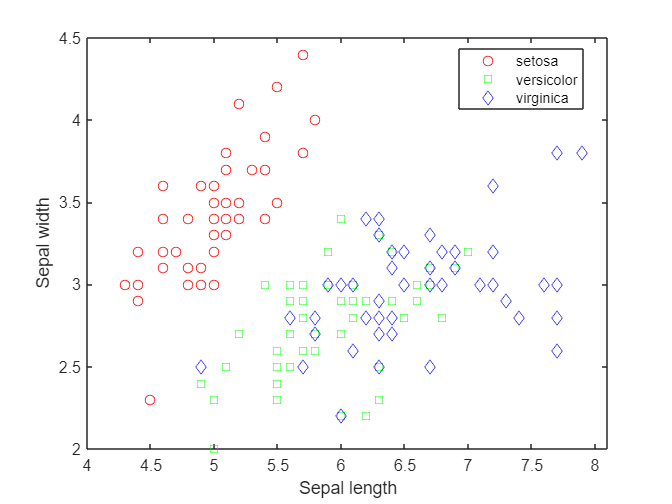

figure;
gscatter(X(:,1), X(:,2), species,'rgb','osd');
xlabel('Sepal length');
ylabel('Sepal width'); 

Split the training and test data. Train a naive Bayes classifier.

myrnd = randperm(150); % iris data have 150 data points.
num_training = round(150*0.8); % using 80% data points for training and the left for testing.

Xtrain= X(myrnd(1:num_training),:);
Ytrain = Y(myrnd(1:num_training));
Xtest = X(myrnd(num_training+1:end),:);
Ytest = Y(myrnd(num_training+1:end));

mdl = fitcnb(Xtrain,Ytrain);

`mdl` is a trained `ClassificationNaiveBayes` classifier.

Predict the iris species and posterior class probabilities of each observation in Xtest using `mdl`.

[predictedspecies,Posterior,~] = predict(mdl,Xtest);

Compute the Accuracy. 

index = cellfun(@strcmp, predictedspecies, Ytest); % predictedspecies and Ytest are cell array.
Acc  = sum(index)/(150-num_training);
disp(['The Accuracy is: ',num2str(Acc*100), '%.'])

The Accuracy is: 80%.


Plot the confusionmatrix.

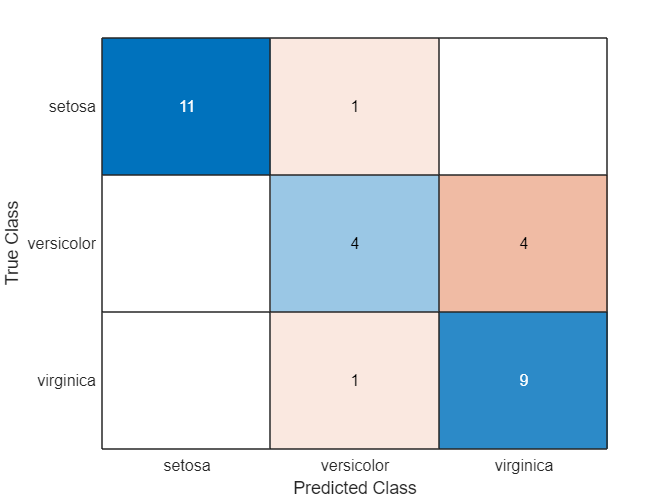

confusionchart(Ytest,predictedspecies) 

Plot the ROC curve.

str = convertCharsToStrings(Ytest);
str = categorical(str);
categories(str)

ans = 3×1 cell array
    {'setosa'    }
    {'versicolor'}
    {'virginica' }


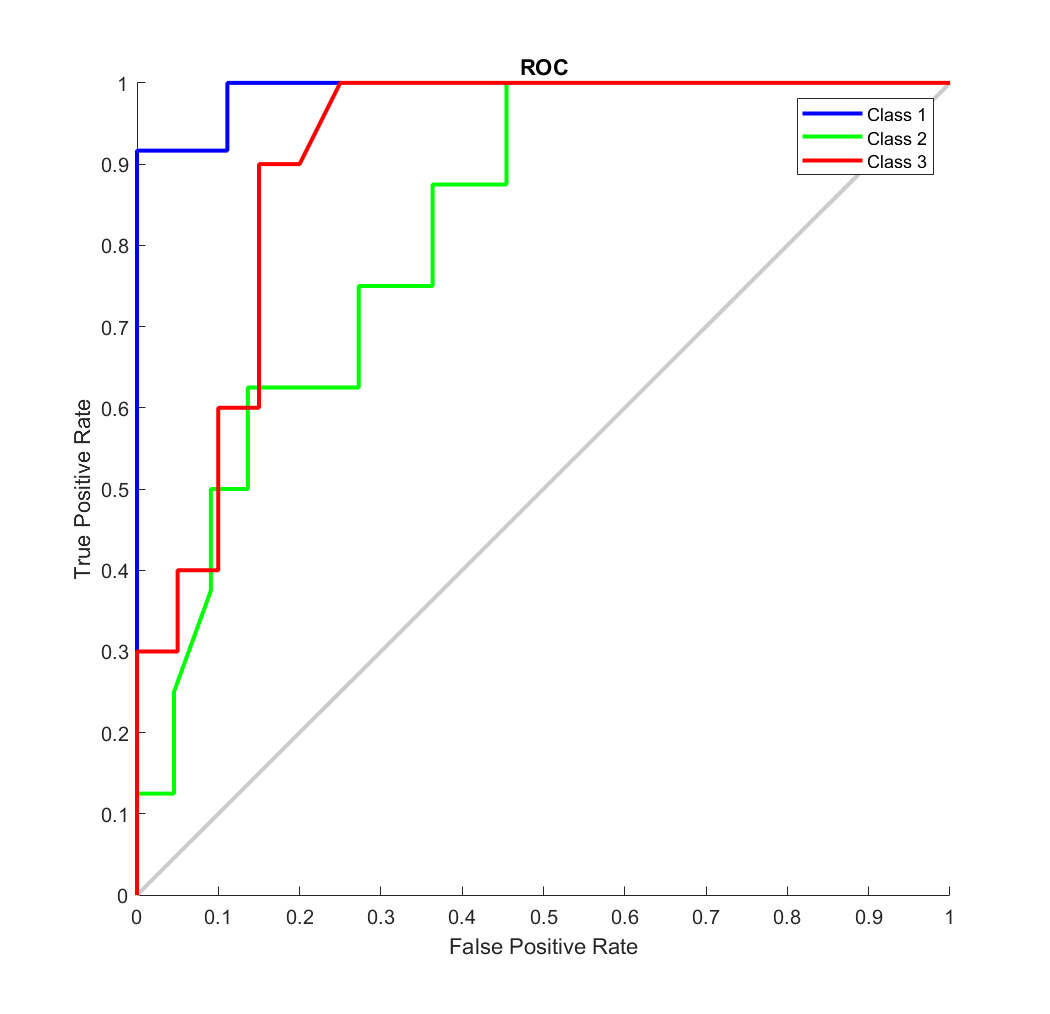

onehotLabels = onehotencode(str,2);
plotroc(onehotLabels',Posterior')